# Excercise 2

## Initializations 

m = 4500;
f = 0.028; % rolling resistance coefficient
g = 9.81;
Ca = 20000; % Cornering stiffness of each tire
lf = 1.01; % length from front tire to the center of mass
lr = 3.32; % length from rear tire to the center of mass
Iz = 29526.2; % Yaw intertia
delT = 0.032;

Symbolics

syms F_input x y wheel_angle psi x_dot y_dot psi_dot X Y s

Setup A and B matrixes 


A = [0                  1                   0                   0
     0             -4*Ca/(m*x_dot)        4*Ca/m        -2*Ca*(lf-lr)/(m*x_dot)
     0                  0                   0                   1
     0      -2*Ca*(lf-lr)/(Iz*x_dot)  2*Ca*(lf-lr)/Iz   -2*Ca*(lf^2+lr^2)/(Iz*x_dot)];
     
B = [0             0
      2*Ca/m        0
      0             0
      2*Ca*lf/Iz    0];

## Question 1 

[Rank1,~,~] = GetRank(2,A,B)      %v = 2m/s

Rank1 = 4

[Rank2,~,~] = GetRank(5,A,B)      %v = 5m/s

Rank2 = 4

[Rank3,~,~] = GetRank(8,A,B)      %v = 8m/s

Rank3 = 4

##  Question 2

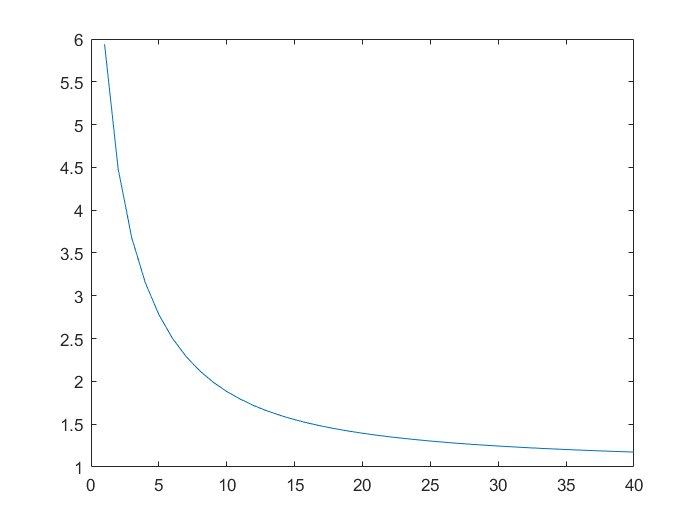

v = 1:1:40;
sigmaratio = [];
poles = [];
for i = 1:40
    [~,ControlMatrix,A_sub] = GetRank(i,A,B);
    [~,SingularVal,~] = svd(ControlMatrix);
    Sigma1 = SingularVal(1,1);
    Sigman = SingularVal(4,4);
    sigmaratio = [sigmaratio log10(Sigma1 / Sigman)]; 
    realpart = real(eig(A_sub));
    poles = [poles realpart];
end
figure(1)
plot(v,sigmaratio)

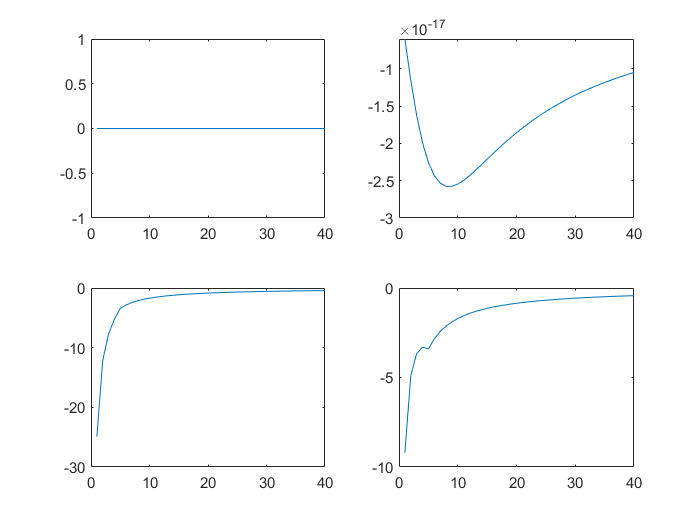

figure(2)
subplot(2,2,1)
plot(v,poles(1,:))
subplot(2,2,2)
plot(v,poles(2,:))
subplot(2,2,3)
plot(v,poles(3,:))
subplot(2,2,4)
plot(v,poles(4,:))

fprintf("The system are both controllable and stable\n");

The system are both controllable and stable


## Question 3

% only heading error
C = [1 0 0 0
     0 0 1 0];
[Rank21,~,~] = GetRank2(2,A,C)      %v = 2m/s

Rank21 = 4

[Rank22,~,~] = GetRank2(5,A,C)      %v = 5m/s

Rank22 = 4

[Rank23,~,~] = GetRank2(8,A,C)      %v = 8m/s

Rank23 = 4

## Question 4

B_SingleInput = [0             
                 2*Ca/m        
                 0             
                 2*Ca*lf/Iz];

p = [-5 -3 -1+0.5j -1-0.5j]

p =   -5.0000 + 0.0000i  -3.0000 + 0.0000i  -1.0000 + 0.5000i  -1.0000 - 0.5000i


disp('First pole design is unstable, vehicle did not folllow the trajectory')

First pole design is unstable, vehicle did not folllow the trajectory


p = [-3 -5 -1+0.5j -1-0.5j]

p =   -3.0000 + 0.0000i  -5.0000 + 0.0000i  -1.0000 + 0.5000i  -1.0000 - 0.5000i


disp('Second pole design is based on the first one while changing the first two pole')

Second pole design is based on the first one while changing the first two pole


disp('vehicle results in the same as first pole design')

vehicle results in the same as first pole design


p = [-5 -3 -2 -1]

p =     -5    -3    -2    -1


disp('Remove imaginary poles results in the vehicle following the trajectory but oscillating')

Remove imaginary poles results in the vehicle following the trajectory but oscillating


disp('Thinking of changing p(2) which correspond to e2')

Thinking of changing p(2) which correspond to e2


p = [-5 -3 -1 -0.1]

p =    -5.0000   -3.0000   -1.0000   -0.1000


disp('p(4) reduced to -0.1 since p(3) need to be reduced and no repeated poles are allowed')

p(4) reduced to -0.1 since p(3) need to be reduced and no repeated poles are allowed


disp('Results are better turning is not ideal')

Results are better turning is not ideal


p = [-15 -25 -1.5 -0.001]

p =   -15.0000  -25.0000   -1.5000   -0.0010


disp('This is the final pole design')

This is the final pole design



[~,~,A_sub] = GetRank(15,A,B_SingleInput);
K = place(A_sub,B_SingleInput,p);

disp('Feedback control matrix K is');

Feedback control matrix K is


disp(K)

$$\left(\begin{array}{cccc} \frac{14721148609532706778437743560200902575852859245}{22835963083295358096932575511191922182123945984} & \frac{42674528965640710916815534536343674362985701166793798196825}{2673158095087128146197513014325757012331295234077669407588352} & \frac{2330201465363030572385382107318032430892621802553945}{1225925842163628004075728383742827150425141916205056} & \frac{18713529963232724436447451667228383090516730200185646259657119}{106926323803485125847900520573030280493251809363106776303534080} \end{array}\right)$$

## Question 5

The final error derivative states has:

error_1 representing result from substraction of Y difference and X difference respect to the lookahead position

error_1dot is the same as introduced which is ydot + xdot * error_2

error_2 represents the difference between psi and psi respecting lookahead position

error_2dot is psidot 